# 2PEM-100A

## `PRACTICE 4_1`

## `Checking all electrical parameters`

`More information:`

- [https://2pem100a.blogspot.com/](https://2pem100a.blogspot.com/)

`More examples:`

- [https://github.com/vasanza/Matlab_Code/tree/Electrical-Systems-Simulation](https://github.com/vasanza/Matlab_Code/tree/Electrical-Systems-Simulation)

- [https://github.com/avbazurt/Simulacion_Sistemas_Electricos](https://github.com/avbazurt/Simulacion_Sistemas_Electricos)

`Dataset:`

- [http://ieee-dataport.org/8630](http://ieee-dataport.org/8630)

Technical information

- Sampling frequency: 4Hz (250mSeg)

**1- Loading a .mat file with 1sample sampling rate / 15min = 1sample / 900seg**

**Data (451x9), donde 451x15min=6765min/60min=112.75horas/24=4.69dias**

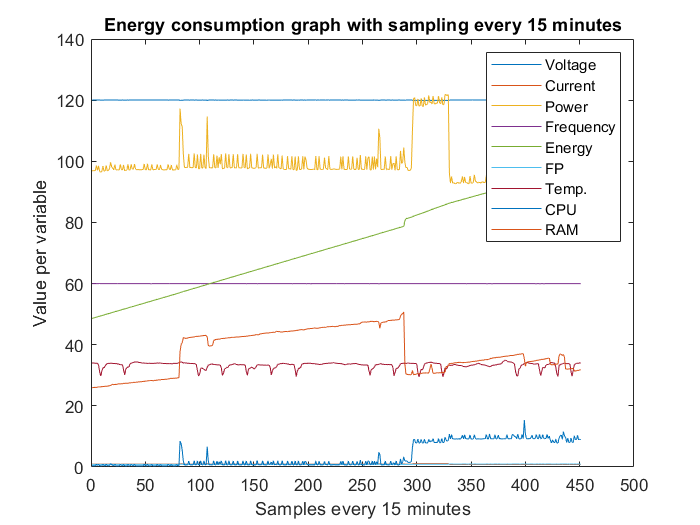

clear;%borra el worskpace
clc;%borra el comand windiw
path=fullfile('./datamean.mat');
data=load(path);
data=struct2cell(data);
data=data{1,1};%table
plot(data);%datos originales
title('Energy consumption graph with sampling every 15 minutes');
legend('Voltage','Current','Power','Frequency','Energy','FP','Temp.','CPU','RAM');

xlabel('Samples every 15 minutes');
ylabel('Value per variable');

# **Example 1: Separate variables**

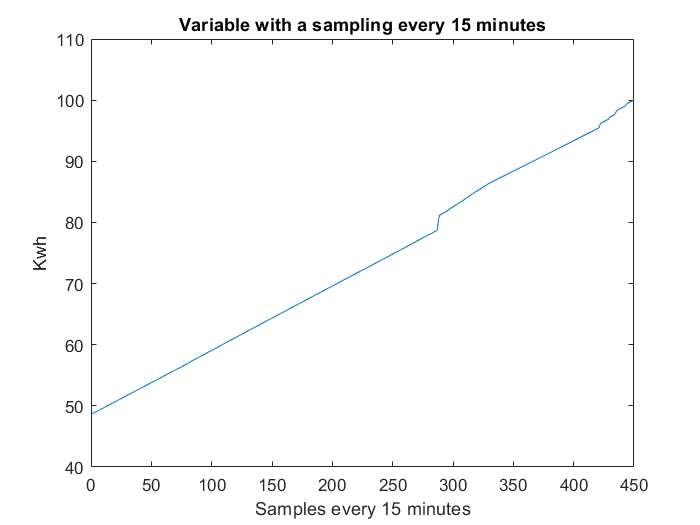

Time=(0:1:length(data)-1)'; %Vector de tiempo
Voltaje=[Time data(:,1)];
Corriente=[Time data(:,2)];
Potencia=[Time data(:,3)];
Frecuencia=[Time data(:,4)];
Energia=[Time data(:,5)];
FP=[Time data(:,6)];
Temp=[Time data(:,7)];
CPU=[Time data(:,8)];
RAM=[Time data(:,9)];


plot(Energia(:,1),Energia(:,2));%datos originales
title('Variable with a sampling every 15 minutes');
%legend('Voltage','Current','Power','Frequency','Energy','FP','Temp.','CPU','RAM');
xlabel('Samples every 15 minutes');
ylabel('Kwh');

# **Example 2: Save CSV file**

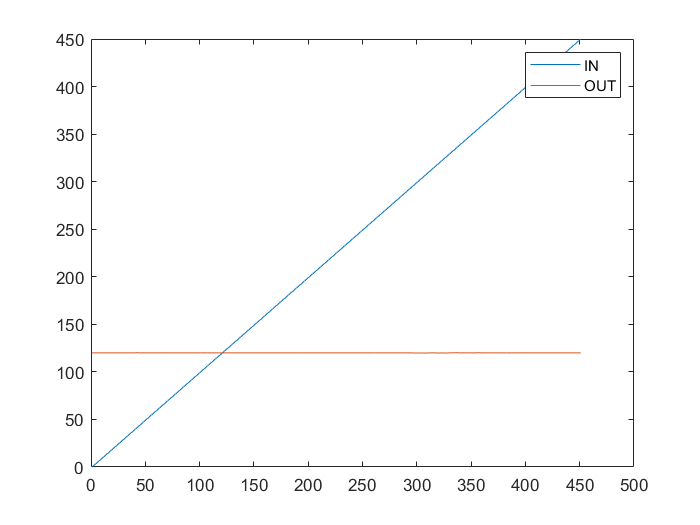

IN=Voltaje(:,1);
OUT=Voltaje(:,2);

plot(IN);
hold on
plot(OUT);
legend('IN','OUT');

%save('Energia.csv',"Energia");

# **Example 3: Calling the System Identification toolbox**

ident